-->Day 2 続き

次に、筋電に由来する電位変動以外を除去するために、バンドパスフィルタで、それ以外の信号を除去しましょう.

#### **Ex.02: 筋電に由来する電位の範囲q1~q2を入れましょう（どこかに答えが書いてあったはず....)。**

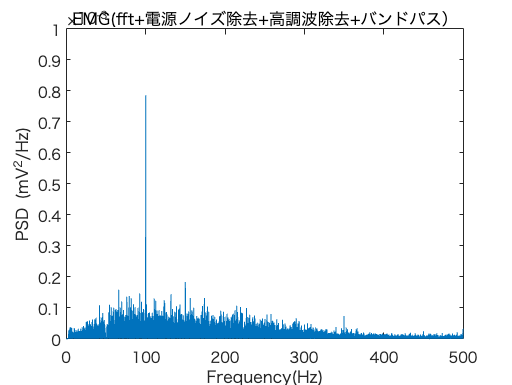

q1= ;%%
q2= ;%%


bpFilt = designfilt('bandpassiir','FilterOrder',20, ...
         'HalfPowerFrequency1',q1,'HalfPowerFrequency2',q2, ...
         'SampleRate',fs);

Ch1_bandpass = filter(bpFilt,Ch1_denoise);
[Ch1_bandpass_pr,f1] = periodogram(Ch1_bandpass ,rectwin(n),n,fs,'ConfidenceLevel',0.95);

plot(f1, Ch1_bandpass_pr)
ylim([0 0.001])
xlabel('Frequency(Hz)')
ylabel('PSD (V^2/Hz)')
title('EMG(fft+電源ノイズ除去+高調波除去+バンドパス）')

以下Highpassやlowpassフィルターを使ってみる場合のコード

Highpass filter

 hpFilt = designfilt('highpassfir','StopbandFrequency',20, ...

         'PassbandFrequency',0.35,'PassbandRipple',0.5, ...

          'StopbandAttenuation',65,'DesignMethod','kaiserwin');

Lowpass filter

 lpFilt = designfilt('lowpassiir','FilterOrder',8, ...

                               'PassbandFrequency',20,'PassbandRipple',0.2, ...

                                 'SampleRate',fs);

取得したデータを保存する.

emgData.time=t;
emgData.emg=Ch1_bandpass; 
%structでなくてもcell配列や、通常の行列でも良いが、必ず時間情報をもあわせて保存すること
save('emgdata.mat','emgData');

次を使用中: save
引数はテキスト スカラーでなければなりません。

%%csv形式で保存したい場合などはそれぞれmatlabのホームページで確認すること

#### **Ex.04: 他のチャンネルも同じように処理し、他チャンネル同士をsubplotで並べ、比較してみましょう.**

(ch_1, ch_2のように出力されるので、for分なり処理部分をfunctionで関数化することで、対応できます）